# 숙제#1: MATLAB 연습 및 인공위성 시스템 조사

**[2026-봄] 인공위성시스템(ASE4080), 인하대학교 항공우주공학과**

**목성훈(shmok@inha.ac.kr)**

% 초기화
clear all; 
close all;
clc;
format long

### 1. MATLAB 연습

#### 1.1. 벡터, 행렬 생성 및 연산

MATLAB는 행렬 연산에 매우 강력한 프로그램이다. 벡터, 행렬은 파이썬처럼 쉽게 정의할 수 있다. 다만, 벡터의 인덱스가 '0'이 아닌 '1'부터 시작한다는 점과 벡터 요소에 접근할 때(인덱싱) 대괄호[]가 아닌 소괄호()를 사용한다는 차이점이 있다.

% 벡터 및 행렬 정의
A = [1, 2, 3];      % 행 벡터 정의
B = [1; 2; 3];      % 열 벡터 정의
C = [1,2; 3,4];     % 행렬(2x2) 정의
A

A =      1     2     3


B

B =      1
     2
     3


C

C =      1     2
     3     4


% 인덱싱
fprintf('A(1) = %f', A(1));

A(1) = 1.000000

fprintf('B(2:3) = [%f, %f]', B(2:3));

B(2:3) = [2.000000, 3.000000]

D = C(1,:)          % 첫 번째 행으로 구성된 부분 행렬

D =      1     2


E = C(:,1)          % 첫 번째 열로 구성된 부분 행렬

E =      1
     3


행렬 연산도 쉽게 수행할 수 있다.


$$\left\lbrack \begin{array}{cc}
1 & 2\\
3 & 4
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
5\\
11
\end{array}\right\rbrack$$


% 벡터 및 행렬 정의
A = [1,2 ; 3,4];
B = [1 ; 2];
C = A*B

C =      5
    11


한편, 등차수열과 같은 균등한 간격의 벡터도 생성할 수 있다. 두 가지 방법을 사용할 수 있다.

% 벡터 생성: 1) 콜론 사용
A = 1 : 2 : 9               % 시작값 : 간격 : 끝값

A =      1     3     5     7     9


% 벡터 생성: 2) linspace 함수 사용
B = linspace(1,11,6)        % linspace(시작값, 끝값, 벡터 성분 개수)

B =      1     3     5     7     9    11


**[숙제1]** 행렬 A를 정의하고 부분행렬 $\left\lbrack \begin{array}{cc}
5 & 6\\
8 & 9
\end{array}\right\rbrack$을 추출하시오.


$$A=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
7 & 8 & 9
\end{array}\right\rbrack$$


% 아래에 코드를 작성하시오.

**[숙제2]** 행렬 B를 정의하고 C = AB를 만족하는 행렬 C를 계산하시오.


$$B=\left\lbrack \begin{array}{c}
1\\
0\\
-1
\end{array}\right\rbrack$$


% 아래에 코드를 작성하시오.

**[숙제3]** 시간 벡터 **t**를 생성하시오. 0초에서 100초까지를 5초 간격으로 나누는 벡터 **t**를 생성하시오. 콜론(:)과 linspace 함수를 각각 이용하시오.

% 아래에 코드를 작성하시오.

#### 1.2. 그래프 그리기

MATLAB을 이용해 그래프를 쉽게 그릴 수 있다. MATLAB은 기본적으로 모든 MATLAB 함수들을 별도의 패키지/라이브러리 로드 없이 사용할 수 있다. 즉, 파이썬과 달리 matplotlib 패키지 로드 없이 그래프 출력이 가능하다.

plot 함수를 이용해 $y=2t$를 만족하는 그래프를 그려본다. 

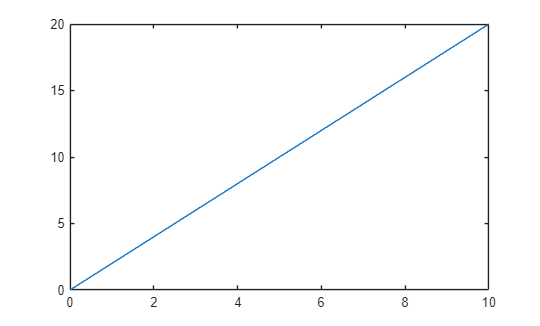

t = 0 : 1 : 10;
y = 2 * t;
figure;
plot(t,y);

축 정의, 그래프 제목 등이 없기에 허전하다. 다양한 plot 관련 함수를 이용해 그래프 편집이 가능하다.

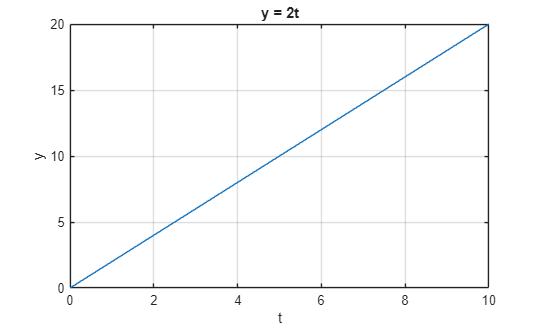

figure;
plot(t,y);
grid on;            % 그리드 추가
xlabel('t');        % x축 제목 추가
ylabel('y');        % y축 제목 추가
title('y = 2t');    % 그래프 제목 추가

**[숙제4]** 1차원 함수 $y_1$과 2차원 함수 $y_2$를 plot 함수로 그리시오.


$$y_1 =-0\ldotp 5t+2$$



$$y_2 =-2{\left(t-2\right)}^2 +5$$


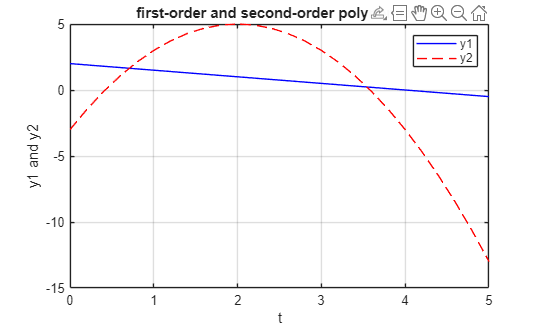

% 아래에 코드를 작성하시오.

#### 1.3. 수치적분

MATLAB의 ode함수들을 이용해 수치적분을 쉽게 수행할 수 있다. 예를 들어, RK45 적분기를 이용해 $y^{\prime } =2t$에 대한 수치적분해를 구하고 이를 해석해 $y=t^2$와 비교하면 다음과 같다.

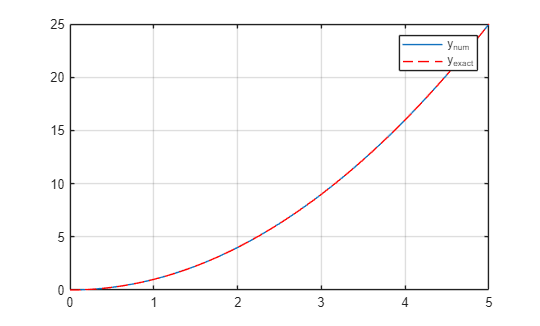

tbound = [0 5];
t = linspace( tbound(1), tbound(2), 100 );
y0 = 0;
[t_num,y_num] = ode45(@(t,y) 2*t, tbound, y0);
y_exact = t.^2;

figure;
plot(t_num,y_num); hold on; grid on;
plot(t, y_exact, 'r--');
legend('y_{num}', 'y_{exact}');

미분방정식 $y^{\prime } =2t$을 함수 f로 정의하고 ode 함수를 사용할 수도 있다.

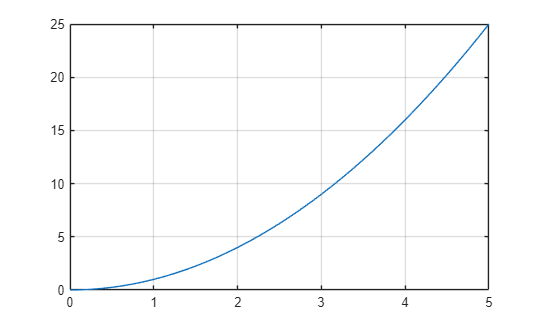

function ydot = f(t,y)
    ydot = 2*t;
end
[t_num,y_num] = ode45(@f, tbound, y0);
figure;
plot(t_num,y_num); hold on; grid on;

**[숙제5]** 초기 상태 $y_0$에 따른 수치 적분 차이를 확인하시오. (for문 사용) 도함수 y' = -2y+2cos(t)sin(2t) 와 같다.

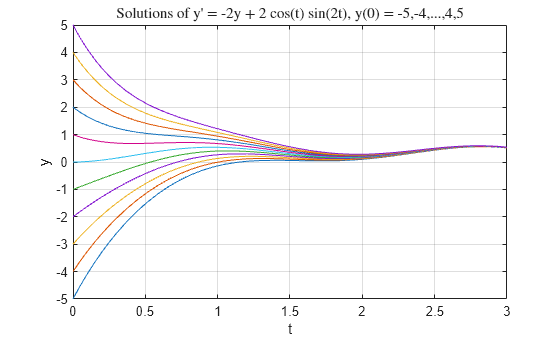

% 아래에 코드를 작성하시오.

### 2. 인공위성 시스템 개념

**[숙제6]** 위성 시스템 중 '발사체'와 '지상체'의 역할을 요약하시오.    분량: *최대 A4 반페이지*

% 작성은 본 파일(matlab live script)을 그대로 활용하거나 다른 문서 편집기(워드, 한글 등)로 작성해도 무방
% 다만, 보고서는 하나의 파일로 통합해 제출해 작성(분리 제출 시 미채점)

**[숙제7]** 큐브샛은 2U, 3U, 6U, 12U, 24U 등 다양한 크기가 존재한다. 국내외 큐브샛 임무들을 조사하고(실제로 개발된(개발중인) 위성만) 크기 별로 그룹을 나누시오. 그룹 별 대표 임무를 선정하고 해당 임무에 대해 요약하시오.   분량: *최대 A4 3페이지*